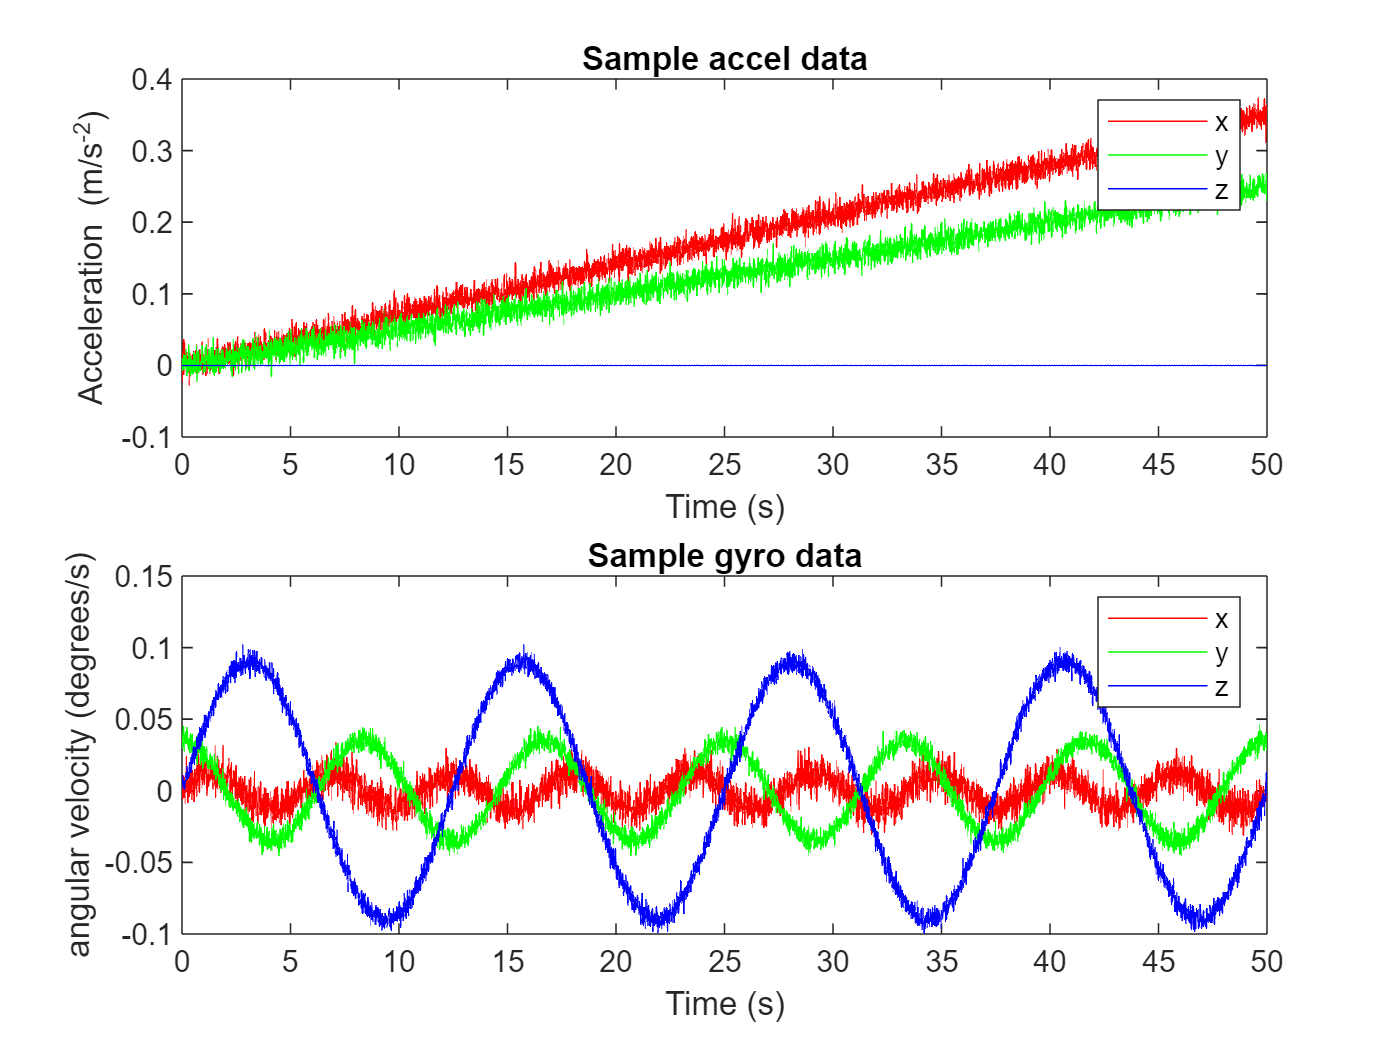

dt = 0.01;
t=0:dt:50;

%sample accelerometer data
accelX = 0.007*t + 0.01*randn(size(t));
accelY = 0.005*t + 0.01*randn(size(t));
accelZ = 0.004*t + 0.01*randn(size(t));
noNoiseMeasurements = [0.007*t;0.005*t ;0.004*t];
%accelNoise = 0.1;
%accelMeasurements = zeros(3, numel(t));
%rotationSpeed = [0.02;0.01;0.005];

%sample gyroscope data
gyroX = 0.012*sin(2*pi*0.18*t)+0.007*randn(size(t)); 
gyroY = 0.035*cos(2*pi*0.12*t)+0.004*randn(size(t)); 
gyroZ = 0.09*sin(2*pi*0.08*t)+0.004*randn(size(t));
%gyroNoise = 0.1;
%gyroMeasurements = cumsum(gyroNoise*randn(3, numel(t)),2);

%for i=2:numel(t)
    %dTheta = gyroMeasurements(:,i)*dt;
    %rotMatrix = eul2rotm(dTheta');
    %accelMeasurements(:,i) = rotMatrix(1:3, 1:2)* [0;0.1];
%end
%accelMeasurements = accelMeasurements + accelNoise*randn(3,numel(t));

accelMeasurements = [accelX; accelY; zeros(1,length(t))]; %Incoming data for accelerometer measurements
gyroMeasurements = [gyroX; gyroY; gyroZ]; %Incoming data for gyroscope measurements

%visualisation
figure;
subplot(2,1,1);
plot(t,accelMeasurements(1,:),'r', t,accelMeasurements(2,:), 'g', t,accelMeasurements(3,:), 'b');
title('Sample accel data');
xlabel('Time (s)');
ylabel('Acceleration (m/s^{-2})');
legend('x','y','z');

subplot(2,1,2);
plot(t,gyroMeasurements(1,:),'r', t,gyroMeasurements(2,:),'g', t,gyroMeasurements(3,:),'b');
title('Sample gyro data');
xlabel('Time (s)');
ylabel('angular velocity (degrees/s)');
legend('x','y','z');

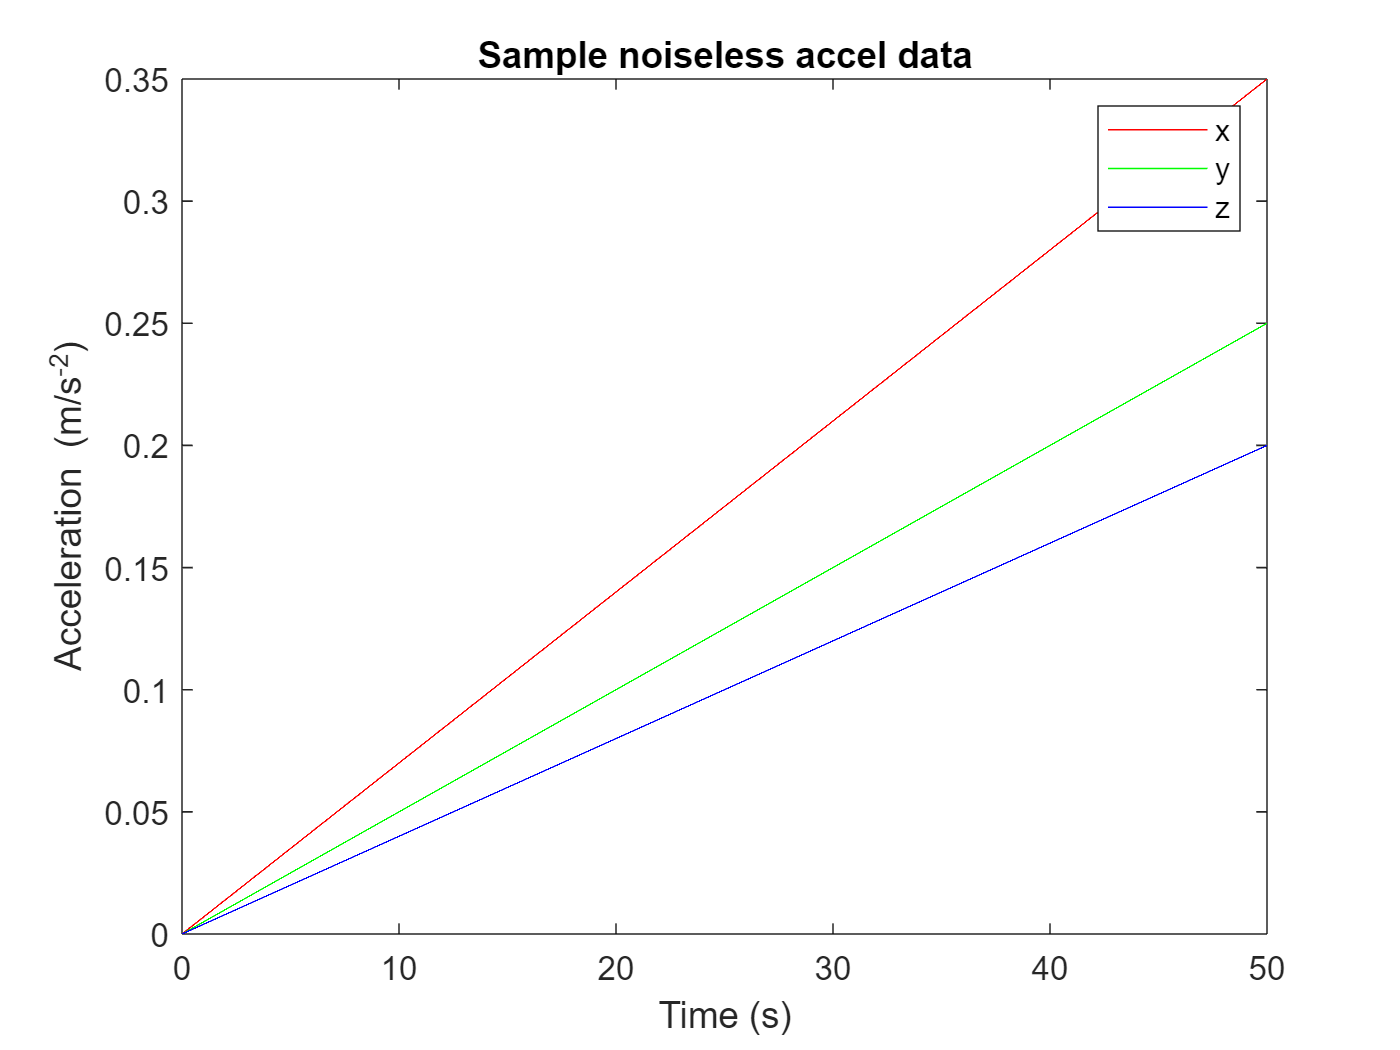

figure;
plot(t,noNoiseMeasurements(1,:),'r', t,noNoiseMeasurements(2,:), 'g', t,noNoiseMeasurements(3,:), 'b');
title('Sample noiseless accel data');
xlabel('Time (s)');
ylabel('Acceleration (m/s^{-2})');
legend('x','y','z');

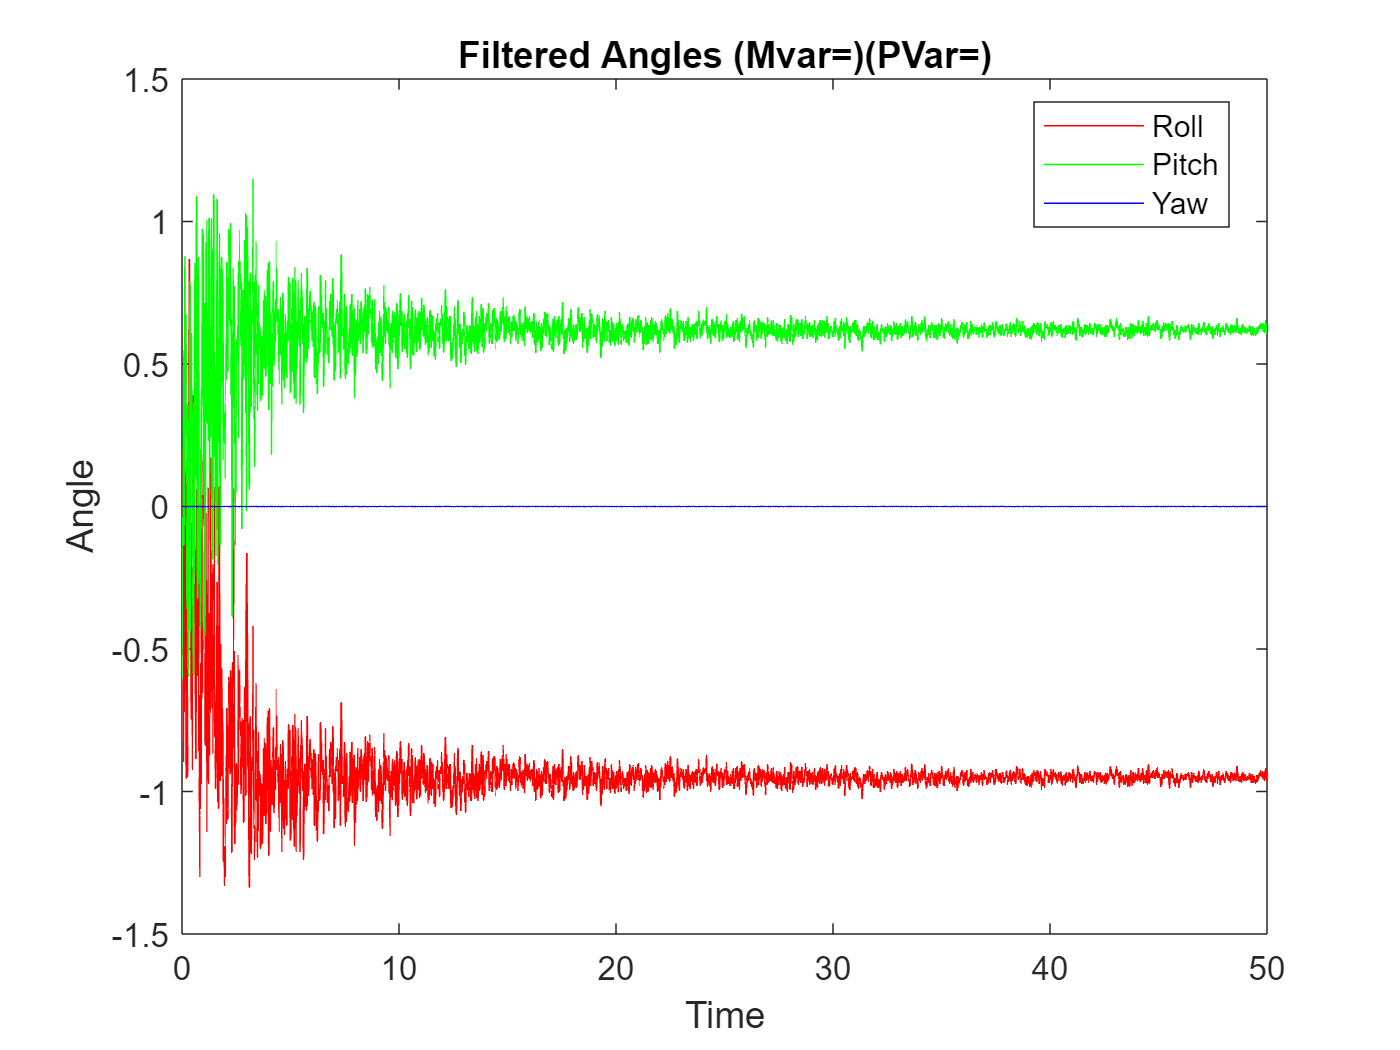



% Initialize variables
xEst = zeros(3,1); %Initial angles (roll, pitch, yaw)
P = eye(3); %Initial estimate covariance
H = eye(3); % Measurement matrix
process_variance = 0.1; Q = process_variance * eye(3);  %Process variance
measurement_variance = 0.4; R = measurement_variance * eye(3);  %Measurement variance
filteredAngles = zeros(3, length(t));

for i=1:length(t)
    % Prediction Step
    A = eye(3) + skew(gyroMeasurements(:,i))*dt;
    xPred = A*xEst;
    errorCovariance = A*P*A' + Q;

    % Update Step
    K = errorCovariance * H' / (H * errorCovariance * H' + R); %Kalman Gain
    eulerangles = acceltoeuler(accelMeasurements(:,i));
    residual = eulerangles'-(H*xPred);
    xEst = xPred + K * residual;
    P = (eye(3) - K * H) * errorCovariance;
    filteredAngles(:, i) = xEst;
end
% Plot
nonKalmanEulerAngles = zeros(3,length(t));
noNoiseAngles = zeros(3, length(t));
for i=1:length(t)
    nonKalmanEulerAngles(:,i) = acceltoeuler(accelMeasurements(:,i));
    noNoiseAngles(:,i) = acceltoeuler(noNoiseMeasurements(:,i));
end
    %No Kalman Calculation
    
figure;

plot(t,filteredAngles(1, :), 'r','DisplayName', 'Roll');
hold on;
plot(t,filteredAngles(2, :), 'g','DisplayName', 'Pitch');
plot(t,filteredAngles(3, :), 'b','DisplayName', 'Yaw');
title('Filtered Angles (Mvar=)(PVar=)');
xlabel('Time');
ylabel('Angle');
legend('Location', 'Best');

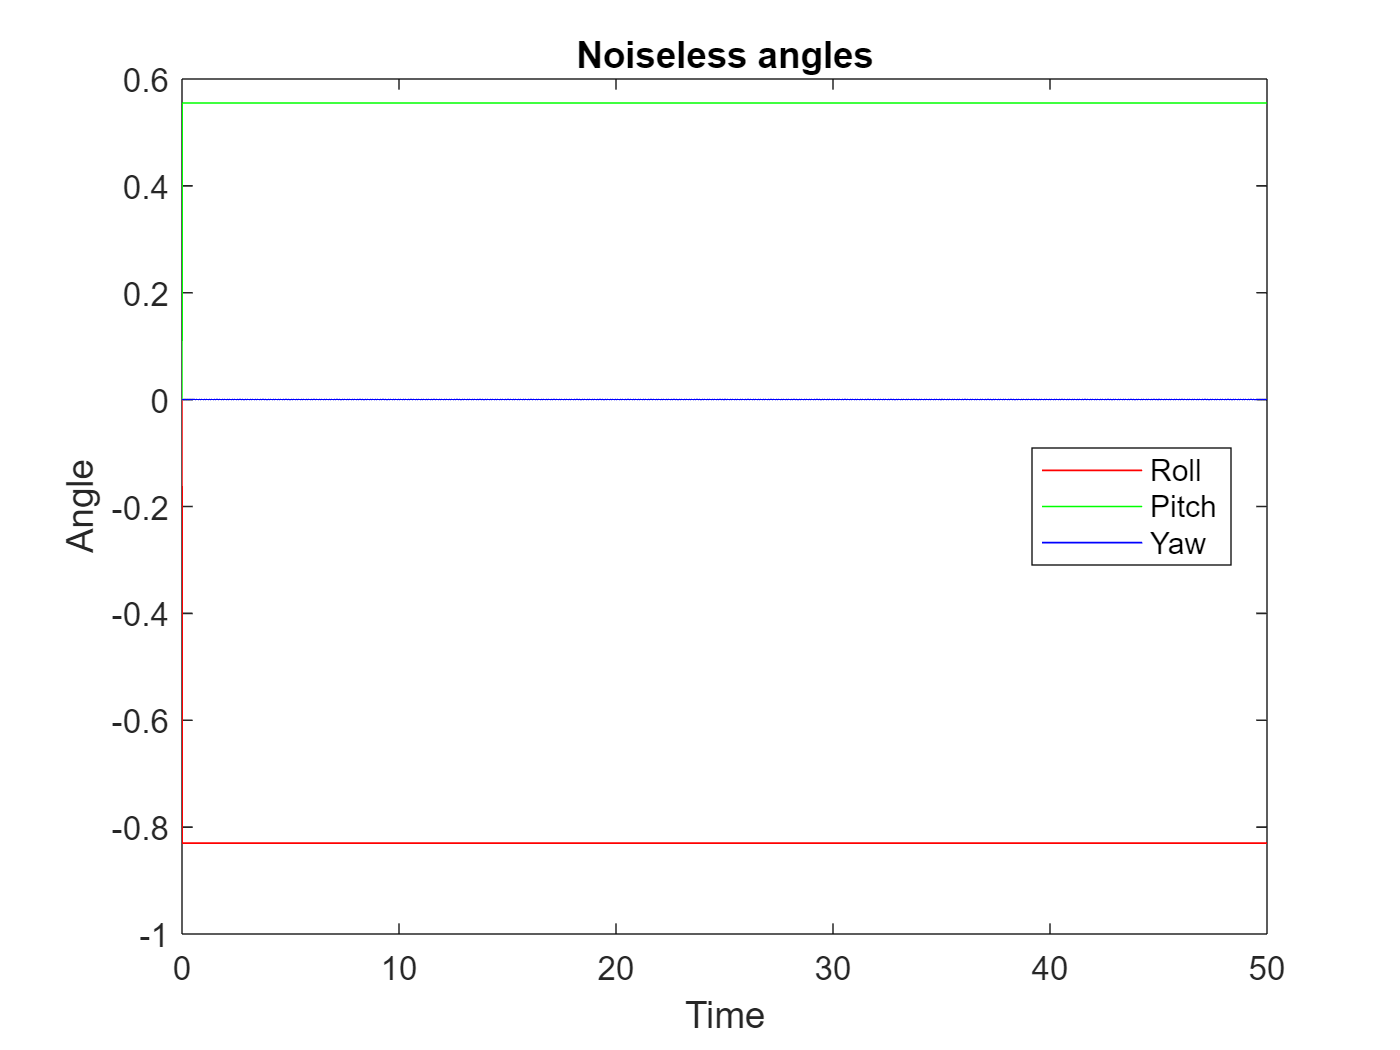

figure;
plot(t,noNoiseAngles(1, :), 'r','DisplayName', 'Roll');
hold on;
plot(t,noNoiseAngles(2, :), 'g','DisplayName', 'Pitch');
plot(t,noNoiseAngles(3, :), 'b','DisplayName', 'Yaw');
title('Noiseless angles');
xlabel('Time');
ylabel('Angle');
legend('Location', 'Best');

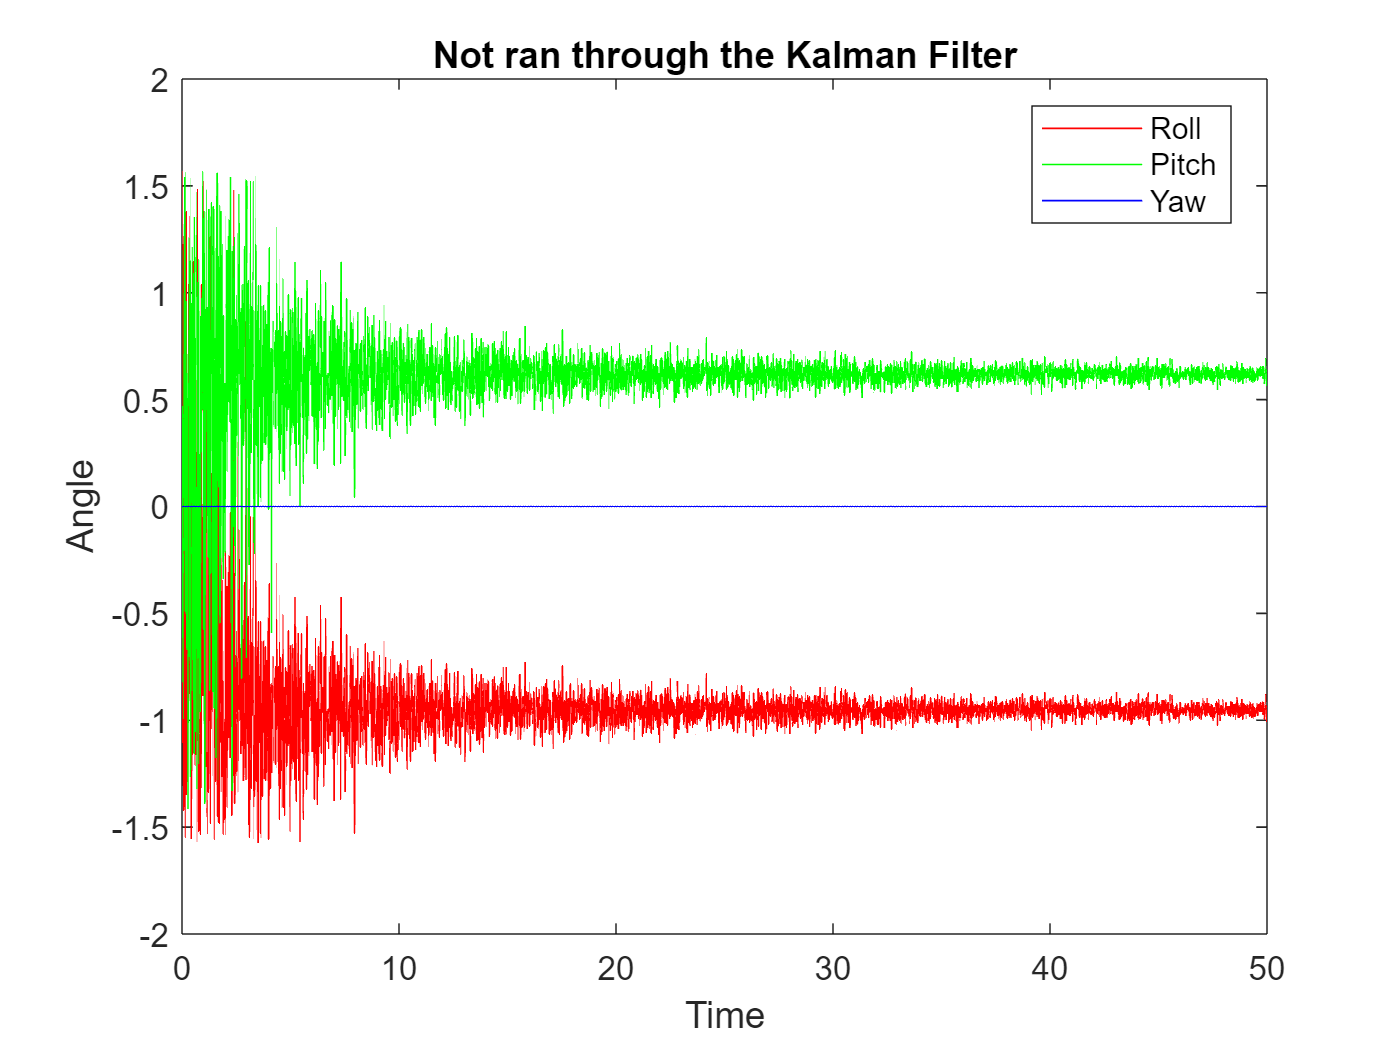

figure;
plot(t,nonKalmanEulerAngles(1, :), 'r','DisplayName', 'Roll');
hold on;
plot(t,nonKalmanEulerAngles(2, :), 'g','DisplayName', 'Pitch');
plot(t,nonKalmanEulerAngles(3, :), 'b','DisplayName', 'Yaw');
title('Not ran through the Kalman Filter');
xlabel('Time');
ylabel('Angle');
legend('Location', 'Best');

function euler = acceltoeuler(accelData)
    pitch = atan2(-accelData(1), sqrt(accelData(2)^2+accelData(3)^2));
    roll = atan2(accelData(2), sqrt(accelData(1)^2 + accelData(3)^2));
    yaw = 0; %if device is initially aligned with the world frame
    euler = [pitch, roll, yaw];
end

function skewer = skew(vec)
    skewer = [0, -vec(3), vec(2); vec(3), 0, -vec(1); -vec(2), vec(1), 0];
end
function filteredAngles = KalmanFilter(processVariance, measurementVariance, t, gyroMeasurements, accelMeasurements,dt)
    xEst = zeros(3,1); %Initial angles (roll, pitch, yaw)
    P = eye(3); %Initial estimate covariance
    H = eye(3); % Measurement matrix
    process_variance = processVariance; Q = process_variance * eye(3);  %Process variance
    measurement_variance = measurementVariance; R = measurement_variance * eye(3);  %Measurement variance
    filteredAngles = zeros(3, length(t));
    for i=1:length(t)
        % Prediction Step
        A = eye(3) + skew(gyroMeasurements(:,i))*dt;
        xPred = A*xEst;
        errorCovariance = A*P*A' + Q;

        % Update Step
        K = errorCovariance * H' / (H * errorCovariance * H' + R); %Kalman Gain
        eulerangles = acceltoeuler(accelMeasurements(:,i));
        residual = eulerangles'-(H*xPred);
        xEst = xPred + K * residual;
        P = (eye(3) - K * H) * errorCovariance;
        filteredAngles(:, i) = xEst;
    end
end
               